# 测试（间接法）

clc
clear
close all
addpath("src\");

## C-W交会

tf = 2000.; % s
x0 = [2200., 8000., 1000., 0., 0., 0.]'; % m, m/s
xf = zeros(6, 1);
p.n = 0.00111; % rad/s
p.tspan = 0.1; % s
umax = 0.01; % N/kg; m/s^2
p.f = 0.01;

### 能量最优

@CostEnergy: $\int ||{\bf{u}}||^2 \mathrm{d}t$

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    2.179119e+06    2.996e+07    8.941e-08
    1      14    8.486741e-02    7.598e-01    2.561e+08    2.334e-02


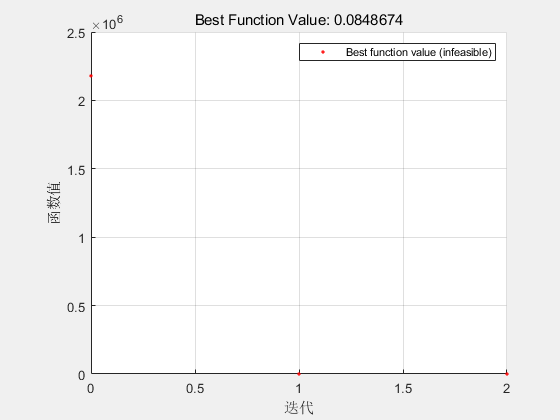


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[s,lambda0,fval,exitflag,output] = IndirOptEnergy(@CwEnergyOpt, x0, xf, tf, p);

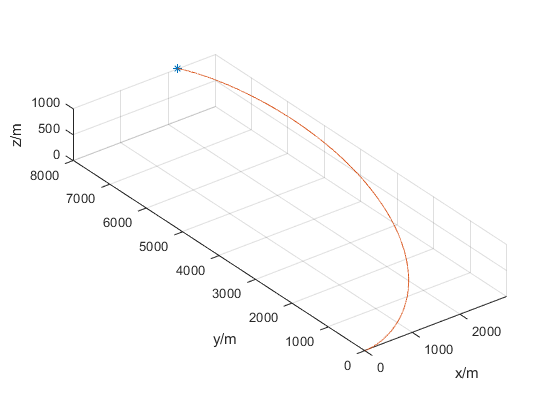

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

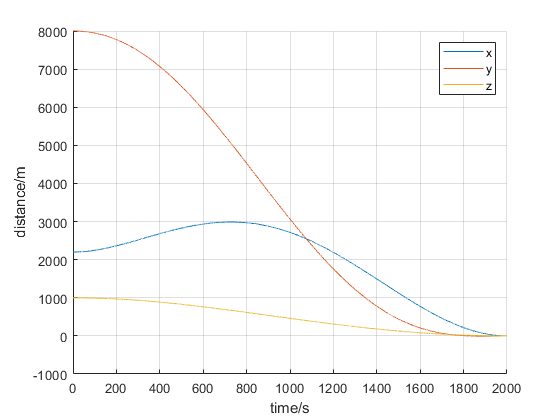

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

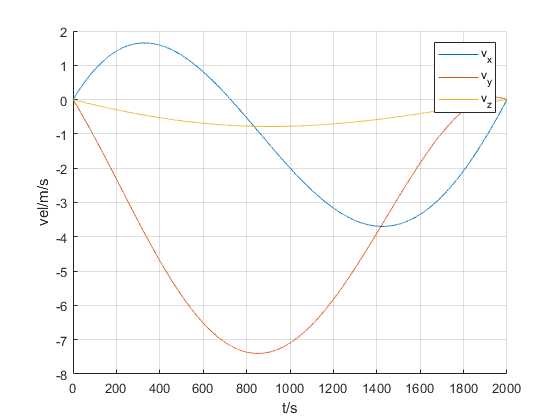

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

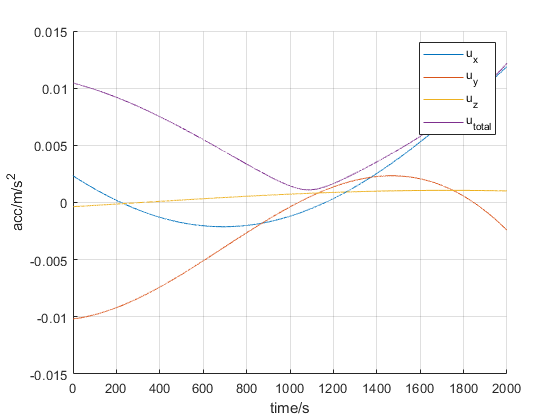

figure
hold on
plot(s(:, 1), s(:, 14 : 17))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

### 燃料最优（同伦）

@CostFuel: $\int \|{\bf{u}}\| \mathrm{d}t$

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    5.455145e-03    1.341e+04    2.220e-16
    1      14    8.194213e-02    4.760e+01    5.799e+04    2.091e+02
    2      21    8.506378e-02    1.153e+00    1.403e+03    4.269e+00
    3      28    8.521574e-02    1.360e-03    2.416e+01    2.010e-01
    4      35    8.521575e-02    2.102e-10    2.526e-03    9.911e-06
    5      42    8.521575e-02    9.565e-12    1.551e-08    1.478e-12

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of th

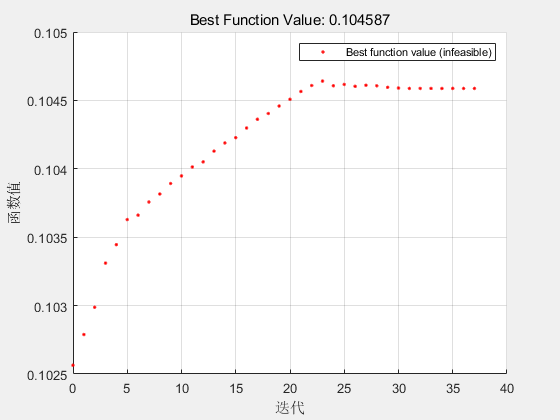


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.



[s,fval,exitflag,output] = IndirOptFuel(@CwFuelOpt, x0, xf, tf, p);

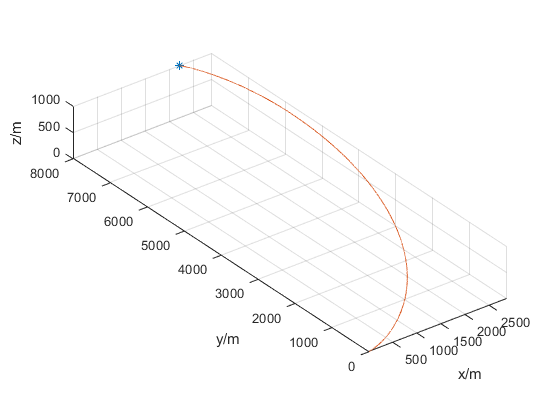

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

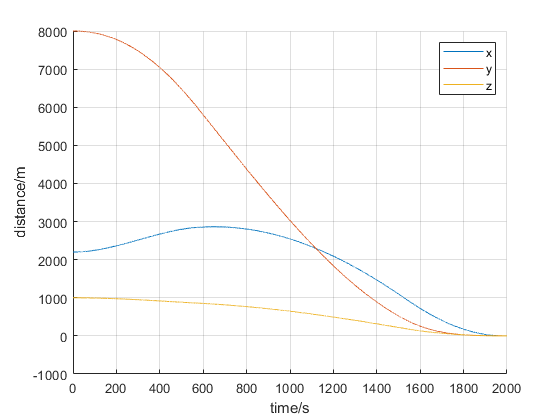

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

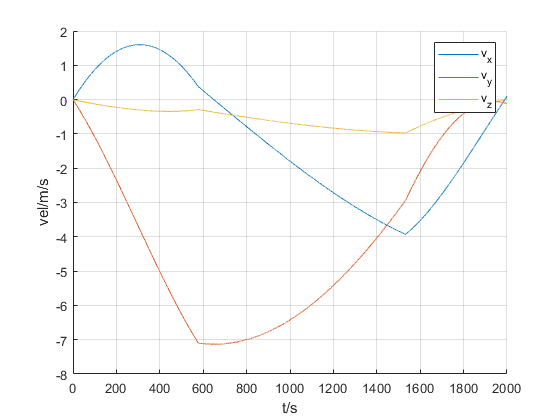

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

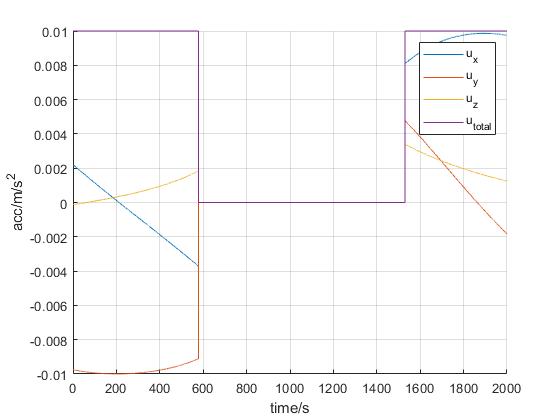

figure
hold on
plot(s(:, 1), s(:, 14 : 17))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

### 时间最优

@CostEnergy: $\int 1 \mathrm{d}t$


Single objective optimization:
4 Variable(s)
3 Nonlinear equality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1            231       1680.96        400.8      0
    2            442       1678.42        398.2      0
    3            653       1635.84          341      0
    4            864       1622.23        332.9      0
    5           1075       1601.86        320.6      0
    6           1286       1595.92        316.9      0
    7           1497       1570.67        297.7      0
    8           1708        1561.1        291.5      0
    9           1919       1548.15        232.9      0
   10           2130       1525.31          212      0
Optimization terminated: maximum number of generations exceeded.


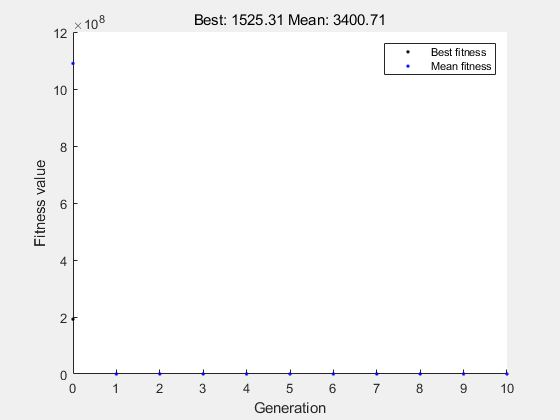

% [s,fval,exitflag,output] = IndirOptTime(@(t, x) CwTimeOpt(t, x, p), x0, xf, tf, p, 1300);
% [s,fval,exitflag,output] = IndirOptTime2(@CwTimeOpt3, x0, xf, tf, p);
% [s,fval,exitflag,output] = IndirOptTime(@(t, x) CwEnergyOpt(t, x, p), x0, xf, tf, p);
% [s,fval,exitflag,output] = IndirOptTime3(@(t, x) CwTimeOpt2(t, x, p), x0, xf, tf, p);
% [s,fval,exitflag,output] = IndirOptTime4(@(t, x) CwTimeOpt(t, x, p), x0, xf, tf, p); % 遗传
[s,fval,exitflag,output] = IndirOptTime5(@(t, x) CwTimeOpt(t, x, p), x0, xf, tf, p); % 遗传

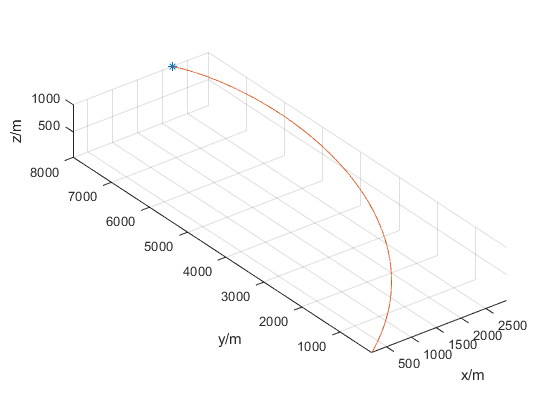

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

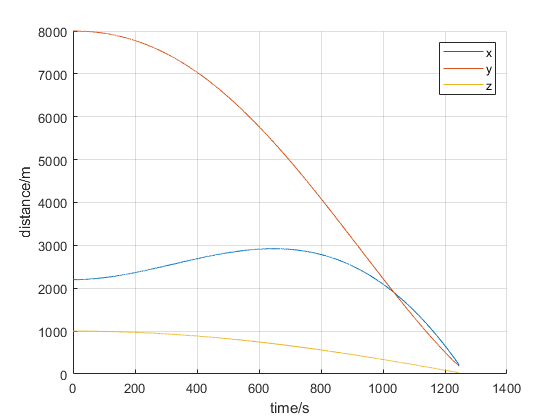

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

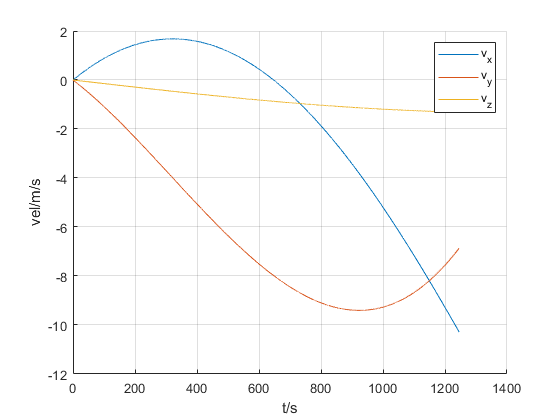

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

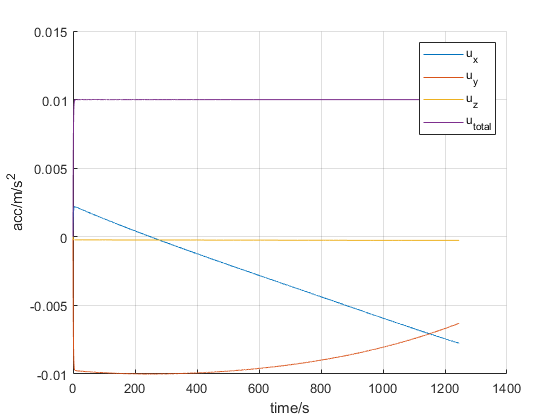

figure
hold on
plot(s(:, 1), s(:, 14 : 17))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.245600e+03    2.118e+02    1.000e+00
    1      10    1.246371e+03    2.076e+02    9.995e-01    1.131e+03
    2      23    1.246377e+03    2.080e+02    1.948e-02    3.854e-01
    3      31    1.246389e+03    2.083e+02    6.116e-02    2.542e-01
    4      39    1.246360e+03    2.086e+02    8.394e-02    9.850e-02
    5      46    1.246318e+03    2.086e+02    4.868e-01    9.129e-02
    6      53    1.246324e+03    2.088e+02    7.481e-02    8.187e-02
    7      61    1.246309e+03    2.089e+02    3.811e-01    6.329e-02
    8      70    1.246319e+03    2.090e+02    3.651e-01    2.300e-02
    9      77    1.246310e+03    2.090e+02    1.477e-01    4.017e-02
   10      85    1.246310e+03    2.091e+02    1.986e-01    3.348e-02
   11      92    1.246303e+03    2.092e+02    2.376e-01    4.380e-02
   12     100    1.246305e+03    2.093e+02    5

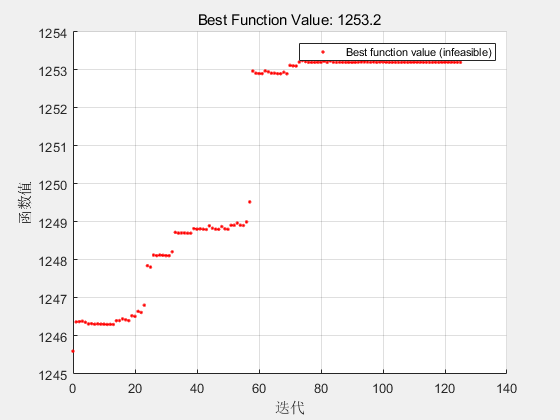


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.



lambda_tf = [s(1, 8 : 13), s(end, 1)]';
% [s,fval,exitflag,output] = IndirOptTime(@(t, x) CwTimeOpt(t, x, p), x0, xf, tf, p, lambda_tf);
[s,fval,exitflag,output] = IndirOptTime6(@(t, x) CwTimeOpt(t, x, p), x0, xf, tf, p, lambda_tf);

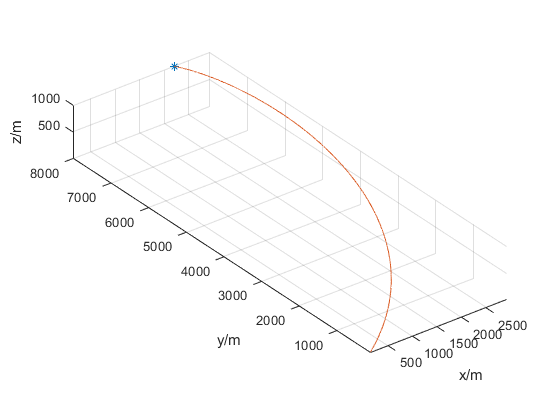

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

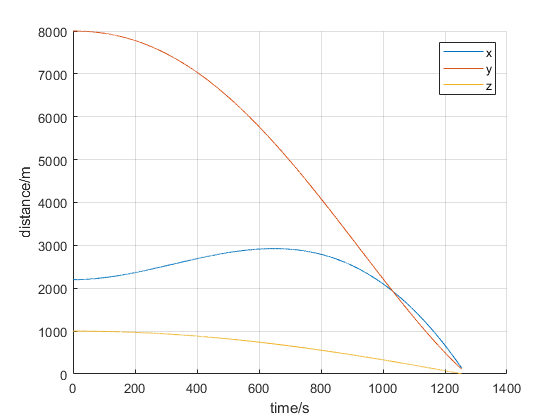

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

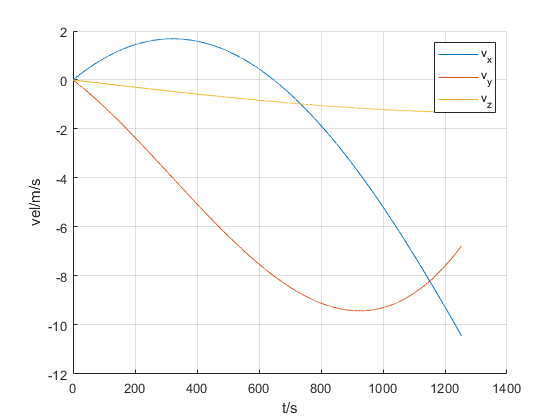

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

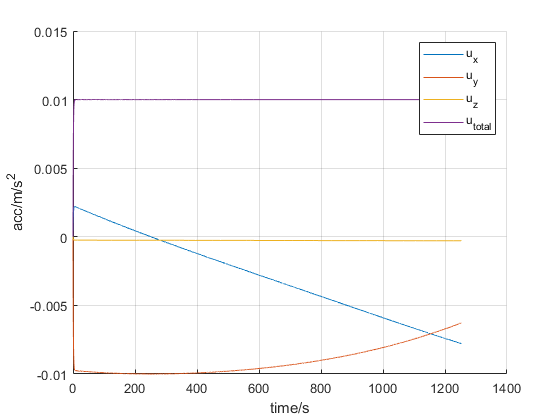

figure
hold on
plot(s(:, 1), s(:, 14 : 17))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off